# 变量

### 变量名：

字母、数字、下划线，区分大小写；

A=1;
a=2;
sum=A+a

sum = 3

### 向量：

如果是等差序列，可使用冒号，简化输入；

如果是升序，默认步长为1；

如果是降序，必须提供步长值；

a= 1:2:10;
a = 1:10;
a = 10:-1:1

a =     10     9     8     7     6     5     4     3     2     1


冒号也可以用于索引的表达。

使用索引时：

Matlab索引从(1)开始；

end表示最后一个索引值；工作区可以查看变量的长度，但不建议使用具体的数值。

a(10);
a(end);
a(1:5);
a(end:-1:1);


### 矩阵表示

1、使用中括号将矩阵的元素括起来；

2、使用"，"和空格分割一行中的元素；使用";"分割行；

d = [1 2 3;4,5,6];
d = [1:5;10:-1:6];

### 数组运算

+, - ,.*, **./**, **.\**

**对元素执行。**

`x = A./B`用 A 的每个元素除以 B 的对应元素。

`x = A.\B` 用 B 的每个元素除以 A 的对应元素。

A = ones(2,3)

A =      1     1     1
     1     1     1


B = [1 2 3; 4 5 6]

B =      1     2     3
     4     5     6


C = A + B;
C=A.*B;
C=A./B;
C=A.\B;

### 矩阵运算

*, /, \, ^, ‘ 

和线性代数的运算规则相同

A = [1 1 1;2 2 2]

A =      1     1     1
     2     2     2


B = [1 2 3; 4 5 6; 7 8 9];
C=A*B;

一般情况下

方程 Ax = B 的解是`x = A\B` 

A = magic(3)

A =      8     1     6
     3     5     7
     4     9     2


B = [15; 15; 15]

B =     15
    15
    15


x = A\B

x =     1.0000
    1.0000
    1.0000


方程 xA = B 的解是`x = B/A` ，`B/A = (A'\B')'`。

A = [1 1 3; 2 0 4; -1 6 -1];
B = [2 19 8];
x = B/A;

# 画图

plot，创建 Y 中数据对 X 中对应值的二维线图。 如果 X 和 Y 都是向量，则它们的长度必须相同；

stem，绘制离散序列数据；

subplot

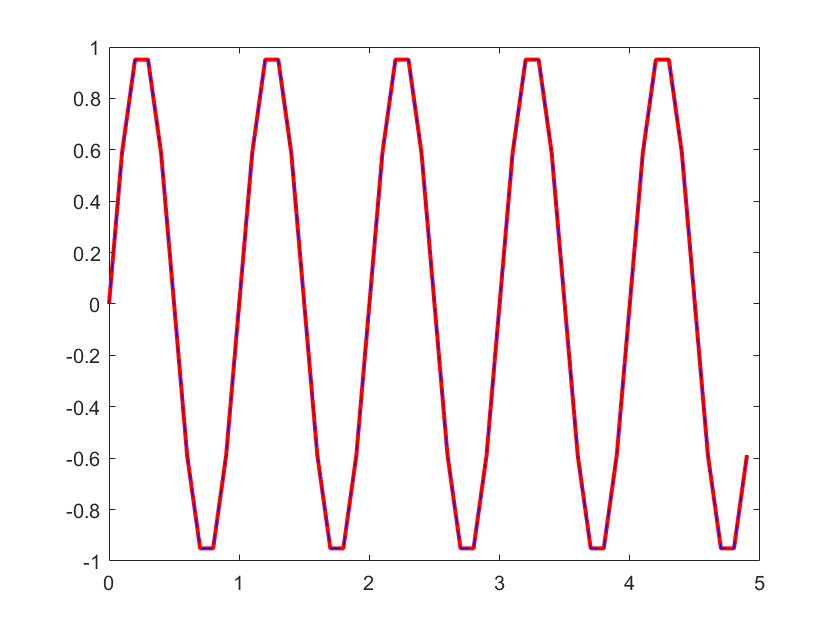

t = 0:0.1:5-0.1;
f = sin(2*pi*t);
plot(t,f,"Color",'r',"LineStyle","-","LineWidth",2); hold on
plot(t,f,"Color",'b',"LineStyle","--","LineWidth",0.5); hold off

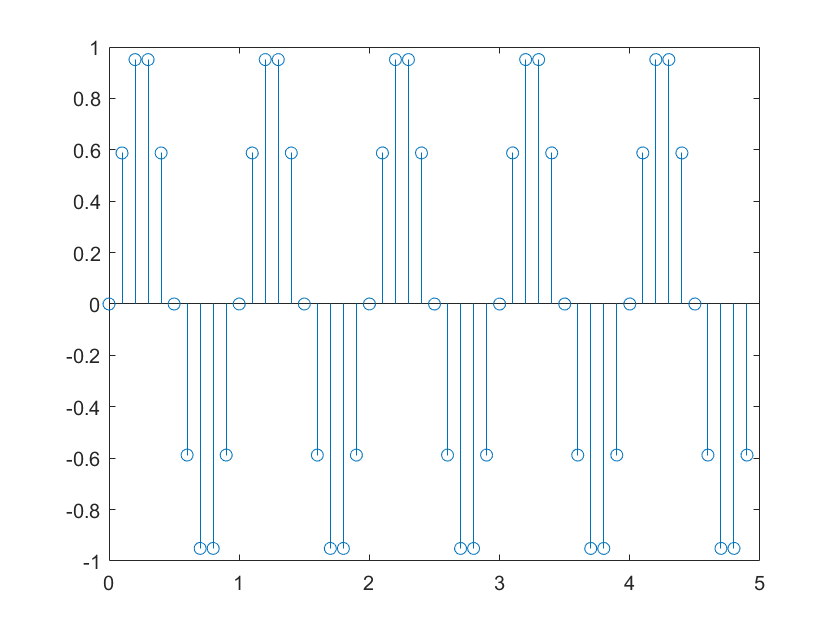

stem(t,f);

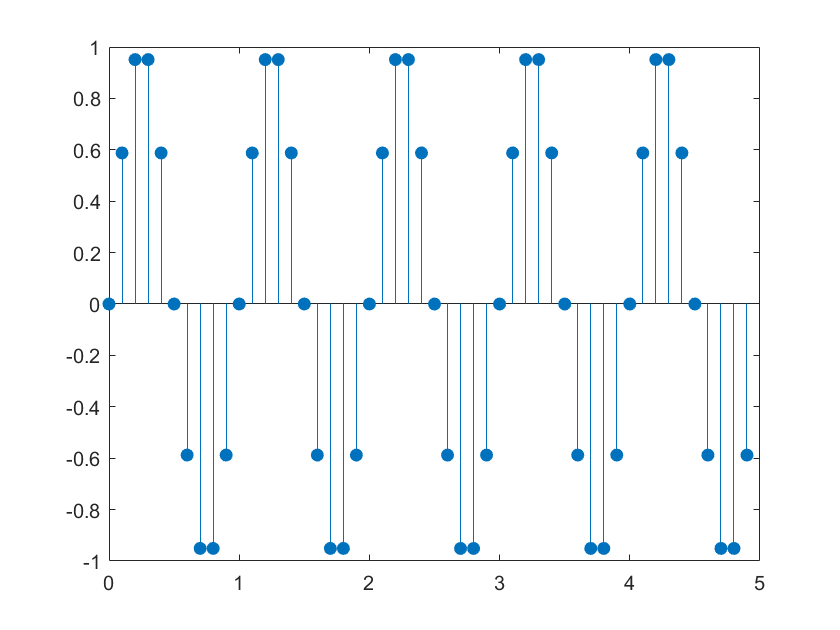

stem(t,f,"filled");

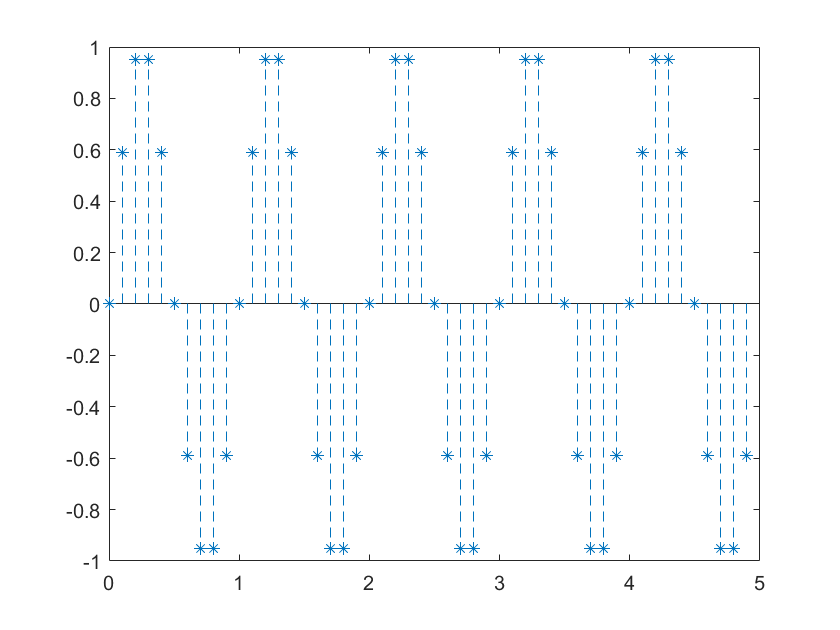

stem(t,f,"LineStyle","--","Marker","*");

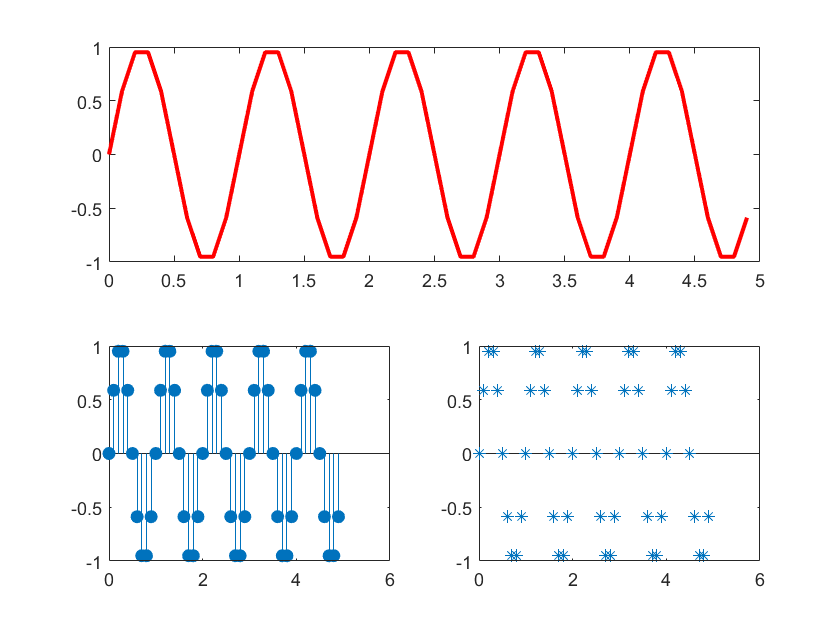

subplot(2,2,[1 2]); plot(t,f,"Color",'r',"LineStyle","-","LineWidth",2);
subplot(2,2,3); stem(t,f,"filled")
subplot(2,2,4); stem(t,f,"LineStyle",'none',"Marker","*")

# 信号表示

### 三角信号：sin(t)，cos(t)  

1、定义自变量

2、按照自变量计算应变量（MATLAB会逐点计算）

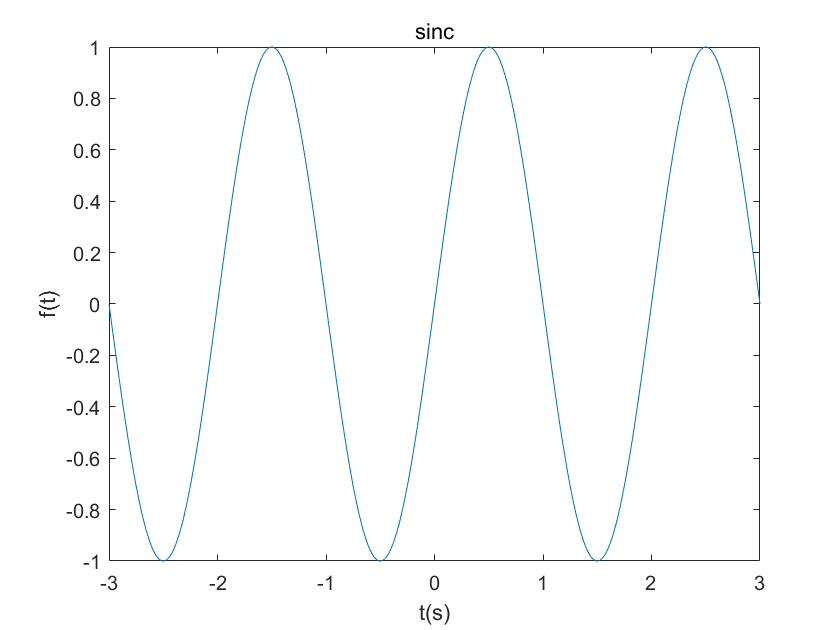

clear; clf;
t = -3:0.01:3;
ft = sin(2*pi*0.5*t);
plot(t,ft); title('sinc'); xlabel('t(s)');ylabel('f(t)');

# 信号操作

### 运算符

加减乘除幂次等

注意区分

使用 .* 运算符即可将两个矩阵或向量的对应元素相乘；

clf清空当前图窗窗口; clear从工作区中删除项目、释放系统内存

clear; clf;
a = [1:3;1:3;1:3];
b = [ones(1,3);ones(1,3);ones(1,3)];
a*b;
a.*b;



### 函数操作：

real  image  abs angle

floor(X)，将 X 的每个元素四舍五入到小于或等于该元素的最接近整数。

ceil(X) 将 X 的每个元素四舍五入到大于或等于该元素的最接近整数。

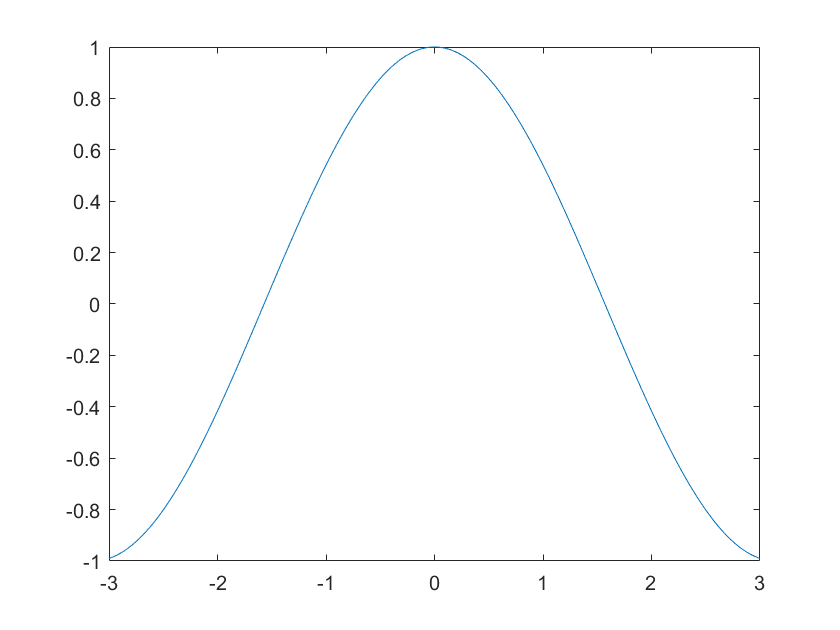

clear; clf;
t = -3:0.01:3;
ft = exp(-1j*t);
plot(t,ft);

figure
plot(t,real(ft));

n = length(ft)

n = 601

floor(n/2)

ans = 300

ceil(n/2)

ans = 301

# 结构

for  if

python中是步进

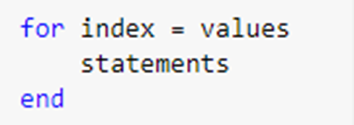

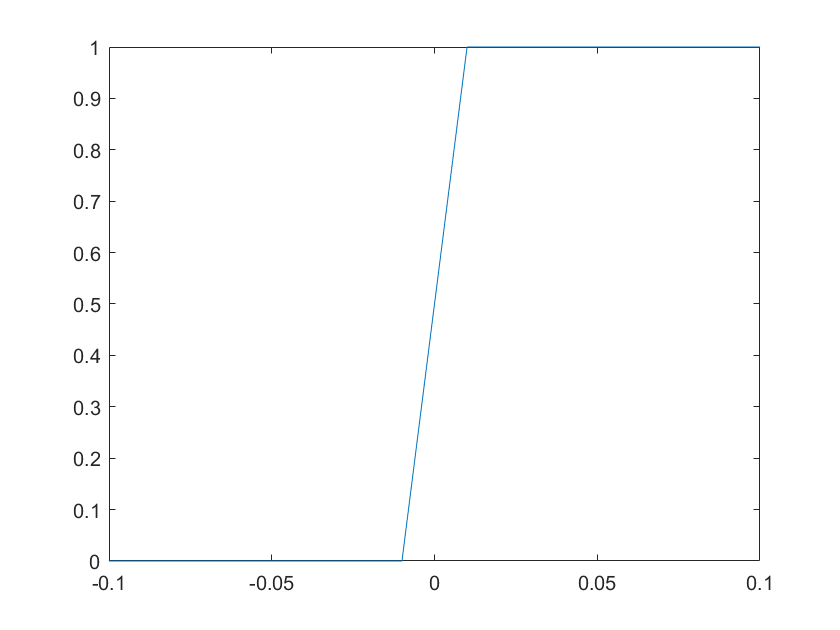

clear; clf;
t = -5:0.01:5;
f = zeros(1,length(t));
for i=1:length(t)
    if t(i)<0
        f(i) = 0;
    elseif t(i)==0
        f(i) = 0.5;
    else
        f(i) = 1;
    end
end
plot(t,f); axis([-0.1 0.1 -inf inf]);